# System parameter calculations

The goal of this script is to compute the dimensions of the various diemnsions of the parts of the 2 stage zero stiffness variable position and mass gravity compensation. It does so using the given constraints, prefrences and part selection 

clear all; close all
addpath("Spring calcuations") %adding path for spring calculations
Trekveren = readtable('Trekveren.xlsx');

#### Material constants

g = 9.81;
%alluminium
E_allu = 69E9; %
sigma_y_allu = 124E6; %steel https://www.steelinox.nl/nl/informatie/roestvast-staal-info
%https://www.gamma.nl/assortiment/plat-profiel-rvs-15x0-5x1000mm/p/B175454
E_steel = 190E9; %[Pa] elastic modulus of steel
sigma_y_steel = 250E6; %[Pa] yield stress steel
%pvc -> https://www.naeff.nl/nl/technische-datasheet/polyvinylchloride-pvc-u?n=2690_3
%https://www.praxis.nl/gereedschap-installatiemateriaal/ijzerwaren/profielen-platen/profielen/alberts-platte-stang-kunststof-wit-25x2mm-1m/5535075
E_pvc = 3000E6; %[Pa]
sigm_y_pvc = 58E6; %[Pa] %flow tension is used, as this is an underirable effect

#### System constants

m_load = 1.2;
m2 = 0.8;                 %[kg] unloaded mass .8
m1 =2.8;                 %[kg] loaded mass 2
m_s2 =1;               %[kg] second stage mass
sys_angle =28/180*pi;  %[rad] angle at which the mirror is located
t = 0.006;               %[m] thickness of plate material that will be used for construction

#### Constraints

h_max = 0.4;             %[m] maximal height mass compensator
sf = 1.1; %safety margin 10%
add_safety_margin = true;
%{
d_mirror = .16;
Longstroke = d_mirror*sin(sys_angle)*3 %[m] stroke of the first stage
S1 = Longstroke*sf 
%}
S1 = 140; %[m] long stroke mechanism
S2 = 10; %[m] short stroke mechanism
S1 = S1*1e-3

S1 = 0.1400

S2 = S2*1e-3

S2 = 0.0100


if add_safety_margin %adding safety margin
    S1 = S1*sf;
    S2 = S2*sf;
end

### parameters

R1 = 0.01;             %[m] inner radius -> constraint by material design of the pulley system
F1 = m1*g + m_s2*g;     %[N] initial load on the system
F2 = m2*g + m_s2*g;     %[N] second loading condition
h_mech = 5*t;           %[m] 5 plate material of space needed for construction
SR = 1/2;               %[] spring elongation ratio used to estimate spring properties

### Desired properties

stage1 = springsystem(F1,F2,S1,h_mech,h_max,SR, R1); %defining the spring system
stage1 = stage1.comp_sys(2) %computing the system properties

stage1 =   springsystem with properties:

              F1: 37.2780
              F2: 17.6580
              L0: 0.1716
              L1: 0.0176
              L2: 0.0083
            Lmax: 0.3432
               S: 0.1540
    springstroke: []
      max_stroke: 0
              R1: 0.0100
              R2: 0.0176
          h_mech: 0.0300
        h_adjust: 0.0093
           h_max: 0.4000
               k: 2.1204e+03
              SR: 0.5000
          Fn_tot: []
              fn: []
            name: []
               n: []


stage1.desired_properties()

    "k = 2120.43"

    "l0 = 171.5834"

    "fn = 171.5804"

    "Fn = 363.8242"



### Spring selection

Bellow various springs parameters are inserted and the function keeps the best spring parameters.

stage1springs = table(); %clearing the table value
for i = 1 : height(Trekveren)
    spring = Trekveren(i,:);
    for j = 1 :2 %Iterating over amount of springs
        springs_sys = stage1.real_spring_properties(spring.Lo, spring.fn, spring.Fn, j); %computing the new spring system with given spring
        spring.('n') = j;                                               %[] number of springs
        spring.('stroke') = springs_sys.max_stroke *1e3;                %[mm] possible stroke of the system
        spring.('S/price') = spring.n * spring.stroke/spring.prijs;     %[mm/€] price per mm stroke
        spring.('enough_stroke') = spring.stroke >= S1*1e3;             %[] determening if desired stroke is reached
        spring.('k') = springs_sys.k;                                   %[n/m] stiffness
        stage1springs = [stage1springs ; spring]; %adding spring to result table
    end
end
stage1springs = sortrows(stage1springs,'k','ascend'); %sorting for lowest stiffness
stage1springs = sortrows(stage1springs,'enough_stroke','descend') %sorting for if desired stroke has been reached

stage1springs = 868×14 table
    Artikelcode     d       Dm      Lo       fn        Fn       R        Materiaal       prijs    n    stroke    S/price    enough_stroke     k  
    ___________    ____    ____    _____    _____    ______    ____    ______________    _____    _    ______    _______    _____________    ____

    {'T1820' }      2.2    21.8      122      188       127    0.58    {'Verenstaal'}     5.37    2    160.41    59.742         true         1351
    {'TR2290'}      3.6    36.4      146      182    253

selected_spring = stage1springs(1,:); %selecting the best spring from the table above
stage1.name = selected_spring.Artikelcode;
stage1.n = selected_spring.n;
stage1 = stage1.real_spring_properties(selected_spring.Lo, selected_spring.fn, selected_spring.Fn, selected_spring.n) %inserting our final spring properties

stage1 =   springsystem with properties:

              F1: 37.2780
              F2: 17.6580
              L0: 0.1220
              L1: 0.0276
              L2: 0.0131
            Lmax: 0.3279
               S: 0.1783
    springstroke: 0.1604
      max_stroke: 0.1604
              R1: 0.0100
              R2: 0.0276
          h_mech: 0.0300
        h_adjust: 0.0145
           h_max: 0.4000
               k: 1351
              SR: 0.5000
          Fn_tot: 254
              fn: 188
            name: {'T1820'}
               n: 2


In the system properties of the first stage it is favorable to have a lager spring stroke than the build stroke S. This means that the spring cannot overextend within the structure.

### Pulley design

Here the dimensions of our desired pulley is computed and exported to pulley.xlsx.

The second loading curve is drawn to show the missmatch in curve in the second loading condition


figure()
clf
hold on
r1 = stage1.R1;
r2 = stage1.R2;
r1 = 1.2

r1 = 1.2000

r2 = 3

r2 = 3

k = stage1.k;
k = 2.5;
n_steps = 1000;
for i = 1:2
    if i == 1 %selecting the loading condition
        F0 = stage1.F2;
    else
        F0 = stage1.F1;
    end
    F0 = 13;
    S = F0*r2/k;
    S = 19.5;
    T = F0*r2/(k*r1);
    stepsize = (r2- r1)/n_steps;
    r = [r1:stepsize:r2];
    theta = - real( sqrt(S^2 - r.^4) )./ (2*(r.^2)) - 0.5 *real(asin((r.^2)/S));
    %theta = - sqrt(S^2 -r.^4)./(2*r.^2) - 0.5 * asin(r.^2/S)
    const = theta(1);
    theta = theta - const; %adding constant such that theta(1) = 0
    %mask = diff(theta) > 0.01; %removing data where theta is no longer increasing
    %theta = theta(mask);
    %r = r(mask);
    
    %theta = [0:0.01:2*pi]; %archimides spiral
    %r = 0.6*theta;
    theta = flip(theta)
    x = real(cos(theta).*r);
    y = real(sin(theta).*r);
    plot(x,y)
    
end

theta =     5.5884    5.5872    5.5861    5.5849    5.5838    5.5826    5.5814    5.5803    5.5791    5.5779    5.5767    5.5756    5.5744    5.5732    5.5720    5.5708    5.5696    5.5684    5.5672    5.5660    5.5648    5.5636    5.5624    5.5612    5.5600    5.5588    5.5576    5.5563    5.5551    5.5539    5.5527    5.5514    5.5502    5.5490    5.5477    5.5465    5.5452    5.5440    5.5427    5.5415    5.5402    5.5390    5.5377    5.5365    5.5352    5.5339    5.5327    5.5314    5.5301    5.5288


theta =     5.5884    5.5872    5.5861    5.5849    5.5838    5.5826    5.5814    5.5803    5.5791    5.5779    5.5767    5.5756    5.5744    5.5732    5.5720    5.5708    5.5696    5.5684    5.5672    5.5660    5.5648    5.5636    5.5624    5.5612    5.5600    5.5588    5.5576    5.5563    5.5551    5.5539    5.5527    5.5514    5.5502    5.5490    5.5477    5.5465    5.5452    5.5440    5.5427    5.5415    5.5402    5.5390    5.5377    5.5365    5.5352    5.5339    5.5327    5.5314    5.5301    5.5288


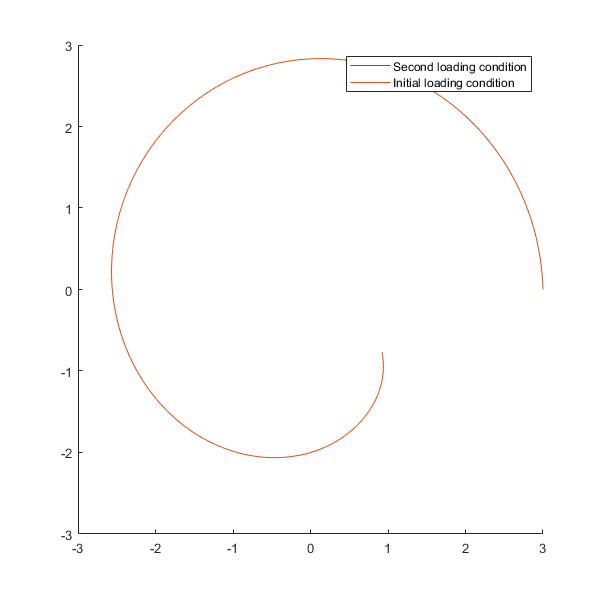


output = table(transpose(x),transpose(y)); %saving data to excel sheet to draw in CAD
writetable(output,'pulley.xlsx');

legend('Second loading condition','Initial loading condition')
set(gcf, 'Position',  [100, 100, 600, 600])


xlim([-r2,r2])
ylim([-r2,r2])

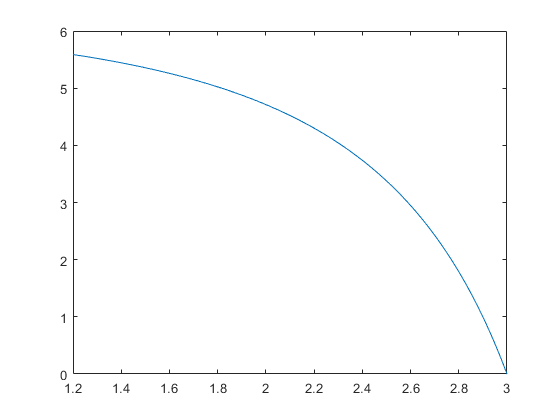

figure
clf
plot(r,theta)

## Analysis Mass transfer spirral pulley

-d xm/r2 = d theta   -> relation angle and displacement mass

d xs / rs = d theta  -> relation angle and displacement spring

xs = rs /r2 d xm -> relation displacement spring vs displacement mass

4 possible positions (2 outer spring positions, 2 loading conditions)


stepsize = 0.01; %1 mm stepsize

x_m = -[0:stepsize:stage1.S]; %[m] possible positions of the mass
x_m = -[0:stepsize:16];
max(theta)

ans = 6.7430

### 1. Initial mass initial spring position

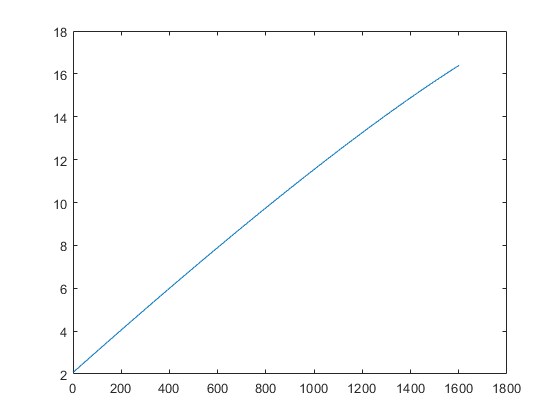

x_s = zeros(1,length(x_m)); %[m] creating empty spring position array
rs = zeros(1,length(x_m)); %[rad] empty array for radius versus angle
validdata = zeros(1,length(x_m));
phi = -x_m / (r2); % [rad] computing the angles that the system will go trough during the stroke of the system
x_s(1) = F0 * (r1/r2) / k;  %initial extension spring
%x_s(1) = stage1.F1 / stage1.k %initial extension spring
rs(1) = r1;
for i = 2 : length(phi) %starting at the second position as the first angle position is zero
    validdata(i) = phi(i) <= max(theta); %if the current angle is greater than the maximal design angle the data is invalid
    [val, idx] = min(abs(theta - phi(i))); %finding the nearest index to the current angle
    rs(i) = r(idx); %finding the pulley radius for the given displacement of the mass
    x_s(i) = x_s(i-1) + rs(i)/r2* stepsize; %computing the next spring position with dx_m is equal to the stepsize
end
figure()
plot(x_s)

spiral_max_stroke = max(-x_m.*validdata) %maximal stroke

spiral_max_stroke = 16

stage1.h_adjust

ans = 0.0145

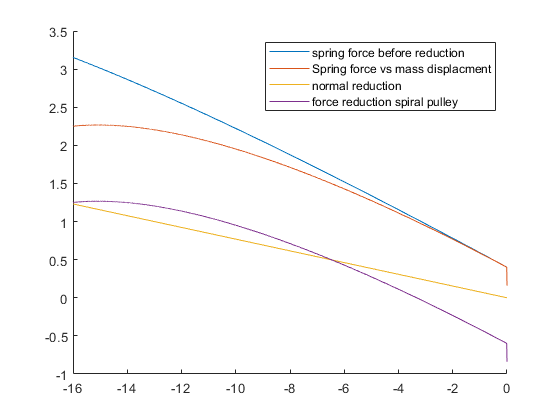

Fs = (x_s)*k; %spring force versus mass displacement
Fs2 = -x_m*k* r1/r2 + F0*(r2/r1) / k - F0; %reduced force spring : [force spring * reduction + initial extension spring - mass 
Fm = Fs.*(rs/r2); %computing the resulting output force
figure()
hold on
%plots are normalized to the initial load
plot(x_m,Fs/F0) 
plot(x_m,Fm/F0)
plot(x_m,Fs2/F0) %reduced spring 
plot(x_m,(Fm-F0)/F0)
legend('spring force before reduction','Spring force vs mass displacment','normal reduction','force reduction spiral pulley')

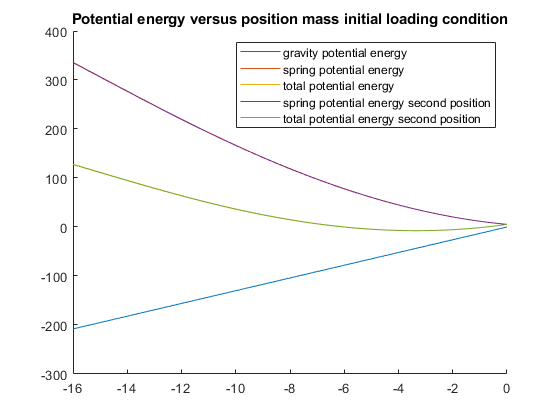


figure()
hold on
gravity_pot_energy = F0*x_m; %gravitational potential energy
spring_pot_energy = 0.5*k*x_s.^2; %spring potential energy intial position
spring_pot_energy2 = 0.5*k*(x_s - stage1.h_adjust).^2; %spring potential energy intial position
tot_pot_energy = gravity_pot_energy + spring_pot_energy;
tot_pot_energy2 = gravity_pot_energy + spring_pot_energy2;
plot(x_m, gravity_pot_energy)
plot(x_m, spring_pot_energy)
plot(x_m,tot_pot_energy)
plot(x_m, spring_pot_energy2)
plot(x_m, tot_pot_energy2)
title('Potential energy versus position mass initial loading condition')
legend('gravity potential energy','spring potential energy','total potential energy', ...
    'spring potential energy second position', 'total potential energy second position ')

### Initial spring position second mass position

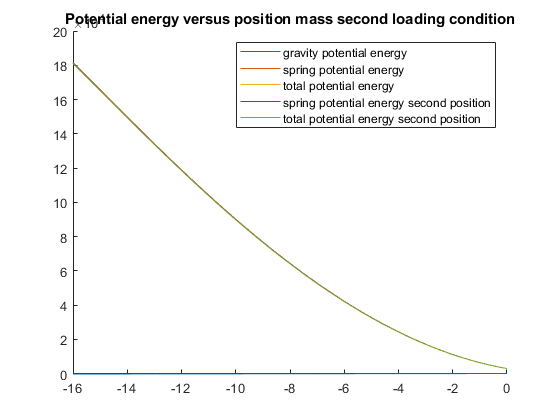

figure()
hold on
gravity_pot_energy = stage1.F2*x_m; %gravitational potential energy
spring_pot_energy = 0.5*stage1.k*x_s.^2; %spring potential energy intial position
spring_pot_energy2 = 0.5*stage1.k*(x_s - stage1.h_adjust).^2; %spring potential energy intial position
tot_pot_energy = gravity_pot_energy + spring_pot_energy;
tot_pot_energy2 = gravity_pot_energy + spring_pot_energy2;
plot(x_m, gravity_pot_energy)
plot(x_m, spring_pot_energy)
plot(x_m,tot_pot_energy)
plot(x_m, spring_pot_energy2)
plot(x_m, tot_pot_energy2)
title('Potential energy versus position mass second loading condition')
legend('gravity potential energy','spring potential energy','total potential energy', ...
    'spring potential energy second position', 'total potential energy second position ')

### Initial mass and second spring position

# Second stage 

The second stage consist out of two parts, the negative spring system and the positive spring system

### parameters

F1 = m1*g;      %[N] initial load on the system
F2 = m2*g;      %[N] second loading condition
reduction = 0.9; %[]desired stiffness reduction ratio
n =4;          %[]number of leaf springs
SR = 1/2;       %[]spring ratio is lower with smaller sizes
h_heigh_control = S2*(1-reduction) %[m] extra height needed to have height control on the output

h_heigh_control = 0.0011

h_plates = 2*t; %height of the plates used in construction
h_ratel = 15e-3; %height needed for ratel
h_top_attachment = 10e-3; %height of the attachment on the top
h_spring_attachments = 0.5e-3 * 2; %height needed for spring attachments
h_mech = h_plates + h_ratel + h_top_attachment + h_spring_attachments + h_heigh_control

h_mech = 0.0391

h_mech = h_mech*1.05 %adding build margin

h_mech = 0.0411

h_max = round(stage1.h_max - 2*stage1.R2 - stage1.max_stroke, 2);%second stage maximal height
h2n = 30e-3; %[m] max heigh negative spring
h2p = h_max - h2n;      %[m] max height positive spring
h_max, h2n, h2p %printing out the resulting dimensions

h_max = 0.1800

h2n = 0.0300

h2p = 0.1500

### Desired positive spring

stage2p = springsystem(F1,F2,S2,h_mech,h2p,SR,0); %creating the secondstage positive spring system
stage2p = stage2p.comp_sys(2) %computing the system parameters

stage2p =   springsystem with properties:

              F1: 27.4680
              F2: 7.8480
              L0: 0.0430
              L1: 0.0320
              L2: 0.0092
            Lmax: 0.0861
               S: 0.0110
    springstroke: []
      max_stroke: 0
              R1: 0
              R2: 0
          h_mech: 0.0411
        h_adjust: 0.0229
           h_max: 0.1500
               k: 857.5100
              SR: 0.5000
          Fn_tot: []
              fn: []
            name: []
               n: []


stage2p.desired_properties() %showing desired spring properties

    "k = 857.51"

    "l0 = 43.0324"

    "fn = 43.0323"

    "Fn = 36.9006"



### Second stage positive spring selection

stage2psprings = table(); %clearing the table value
for i = 1 : height(Trekveren)
    spring = Trekveren(i,:);
    for j = 1 :2 %Iterating over amount of springs
        springs_sys = stage2p.real_spring_properties(spring.Lo, spring.fn, spring.Fn, j); %computing the new spring system with given spring
        spring.('n') = j;                                               %[] number of springs
        spring.('stroke') = springs_sys.max_stroke *1e3;                %[mm] possible stroke of the system
        spring.('S/price') = spring.n * spring.stroke/spring.prijs;     %[mm/€] price per mm stroke
        spring.('enough_stroke') = spring.stroke >= S2*1e3;             %[] determening if desired stroke is reached
        spring.('k') = springs_sys.k;                                   %[n/m] stiffness
        stage2psprings = [stage2psprings ; spring]; %adding spring to result table
    end
end
stage2psprings = sortrows(stage2psprings,'k','ascend'); %sorting for lowest stiffness
stage2psprings = sortrows(stage2psprings,'enough_stroke','descend') %sorting for if desired stroke has been reached

stage2psprings = 868×14 table
    Artikelcode     d      Dm      Lo      fn      Fn      R        Materiaal       prijs    n    stroke    S/price    enough_stroke     k  
    ___________    ___    ____    ____    ____    ____    ____    ______________    _____    _    ______    _______    _____________    ____

    {'T810'  }     0.9     9.1    36.5    57.6      24    0.35    {'Verenstaal'}    2.66     2    15.917    11.968         true          833
    {'TR1060'}     1.1    10.9    44.3    66.1    29.8    0.38    {'RV

selected_spring = stage2psprings(1,:); %selecting the best spring from the table above
stage2p.name = selected_spring.Artikelcode;5

ans = 5

stage2p.n = selected_spring.n;
stage2p = stage2p.real_spring_properties(selected_spring.Lo, selected_spring.fn, selected_spring.Fn, selected_spring.n) %inserting our final spring properties

stage2p =   springsystem with properties:

              F1: 27.4680
              F2: 7.8480
              L0: 0.0365
              L1: 0.0330
              L2: 0.0094
            Lmax: 0.0854
               S: 0.0159
    springstroke: 0.0246
      max_stroke: 0.0159
              R1: 0
              R2: 0
          h_mech: 0.0411
        h_adjust: 0.0236
           h_max: 0.1500
               k: 833
              SR: 0.5000
          Fn_tot: 48
              fn: 57.6000
            name: {'T810'}
               n: 2


again more spring stroke is desired such that the end stop of the negative spring will be hit first before the spring is overextended 

stage2p.S = S2;

### Negative spring design

Below are the design parameters of the negative spring design

kn = round(stage2p.k*reduction) %desired negative spring stiffness

kn = 750

E = E_steel; %selecting material properties
sigma_y = sigma_y_steel;
t = 0.0005; %[m] thickness plate steel
b = 0.015; %[m] widht plate steel

#### Viability short stroke 

Below are computation to estimate the viability of the system

I = t^3*b/12; %[m^4]  moment of inertia leaf spring
%L_desired = ( ( (S2)^2 * 53 * E *t)/(sigma_y*5/3) )^(1/3) %leaf spring length given the desired stroke
stage2n = negative_spring(E_steel,sigma_y,t,b,n,kn)

stage2n =   negative_spring with properties:

          E: 1.9000e+11
    sigma_y: 250000000
          t: 5.0000e-04
          b: 0.0150
          n: 4
         sm: 0.8700
          I: 1.5625e-13
          L: 0.1916
          k: 750
     uz_max: 0.0018
          S: 0.0210


### Performance

resulting_stiffness = stage2p.k - stage2n.k

resulting_stiffness = 83

real_reduction = 1- resulting_stiffness/stage2p.k

real_reduction = 0.9004

max_stoorkracht = resulting_stiffness*S2

max_stoorkracht = 0.9130

stoorkracht_perc = max_stoorkracht / F1 * 100 %[perocent]

stoorkracht_perc = 3.3239

# Second stage imperfection analysis

It is not possible to build to the micrometer perfectly, therefore we have to be sure that even given imperfect parts that are system is still **tunable **such that it is opertable and that given the build margin it is still stable.

threadpitch = 0.7; %[mm] thread pitch m4 bolt
displacement_per_rotation = threadpitch / (1 - real_reduction)

displacement_per_rotation = 7.0253

%thread pitch is the distance traveled by one rotation
springmargin =1.1; %spring max load and stiffness can be off by 10 percent
buildmargin = 5e-3; %[m] construction can be within 10 mm

### Lower positive stiffness and higher negative stiffness

The possitive spring can be off by 10 % -> however we can adjust the negative stiffness by adjusting L -> how accurate does this have to be?

stage2n.L = stage2n.L - buildmargin;
stage2n = stage2n.comp_stiff()

stage2n =   negative_spring with properties:

          E: 1.9000e+11
    sigma_y: 250000000
          t: 5.0000e-04
          b: 0.0150
          n: 4
         sm: 0.8700
          I: 1.5625e-13
          L: 0.1866
          k: 811
     uz_max: 0.0018
          S: 0.0210


resulting_k =  stage2p.k - stage2n.k

resulting_k = 22

real_ratio = 1-resulting_k/stage2p.k

real_ratio = 0.9736

# Summary

stage1, stage2p, stage2n

stage1 =   springsystem with properties:

              F1: 37.2780
              F2: 17.6580
              L0: 0.1220
              L1: 0.0276
              L2: 0.0131
            Lmax: 0.3279
               S: 0.1783
    springstroke: 0.1604
      max_stroke: 0.1604
              R1: 0.0100
              R2: 0.0276
          h_mech: 0.0300
        h_adjust: 0.0145
           h_max: 0.4000
               k: 1351
              SR: 0.5000
          Fn_tot: 254
              fn: 188
            name: {'T1820'}
               n: 2


stage2p =   springsystem with properties:

              F1: 27.4680
              F2: 7.8480
              L0: 0.0365
              L1: 0.0330
              L2: 0.0094
            Lmax: 0.0854
               S: 0.0110
    springstroke: 0.0246
      max_stroke: 0.0159
              R1: 0
              R2: 0
          h_mech: 0.0411
        h_adjust: 0.0236
           h_max: 0.1500
               k: 833
              SR: 0.5000
          Fn_tot: 48
              fn: 57.6000
            name: {'T810'}
               n: 2


stage2n =   negative_spring with properties:

          E: 1.9000e+11
    sigma_y: 250000000
          t: 5.0000e-04
          b: 0.0150
          n: 4
         sm: 0.8700
          I: 1.5625e-13
          L: 0.1866
          k: 811
     uz_max: 0.0018
          S: 0.0210


## Connecting rods

The two stages are connected trough threaded rods, here the stiffness is compared to the stiffness of the negative spring

It has to be sufficiently stiff such that it does not influence the performance of the negative springs

d = 6

d = 6

r = d/2 * 1e-3;
L = 200e-3;
I = pi / 4 * r^4;
k = round(3*E_steel*I/L^3)*2

k = 9066


k/kn

ans = 12.0880

### Final mechanism height negative spring

h_ratel = 10; %height needed for ratel and insertion room
h_attachment = 10; %height needed for attachment point at the top
h_plates = 6*2

h_plates = 12

F = stage2n.k*S2

F = 8.9210

F/k*1e3

ans = 0.9840

stage2p.h_mech

ans = 0.0411